# Gradient Descent vs Newton's method for non-convex problems

We look at a 2D problem with local minima, local maxima, and a saddle point.

Stephen Becker

June 2018, Cambridge/CCIMI Optimisation short-course

September 2019, AIMS South Africa Optimization short-course

Terminology: for smooth unconstrained problems, a **stationary point** is any point where the gradient is zero. We can classify stationary points into 3 types: **local min**,** local max**, and **saddle points**. We are defining saddle points as any stationary point that is not a local min nor a local  max.

Unless we are very unlucky on the starting point, **gradient descent** will always converge to a local minimizer (in fact, for this toy problem we discuss, this holds rigorously; see "[Gradient Descent Converges to Minimizers](https://arxiv.org/abs/1602.04915)" by Jason D. Lee, Max Simchowitz, Michael I. Jordan, Benjamin Recht; 2016).  However, gradient descent can be *slowed down* by the presence of the saddle point.

**Newton's method**, on the other hand, can converge to a saddle point or even a local max! This is quite undesirable. Why does it do this? It is trying to solve the stationarity equations (which treat all local min, local max, and saddle points equally), and it finds whichever stationary point is closest. [For real applications, no one uses plain Newton without any kind of safe guard, or at least they ought not to, but there is still a problem with saddle points]

See "[Identifying and attacking the saddle point problem in high-dimensional non-convex optimization](https://arxiv.org/abs/1406.2572)" by Yann Dauphin, Razvan Pascanu, Caglar Gulcehre, Kyunghyun Cho, Surya Ganguli, Yoshua Bengio (NIPS 2014)

On the other hand, at least Newton's method converges to these undesirable points very quickly...

Some code to setup our example:

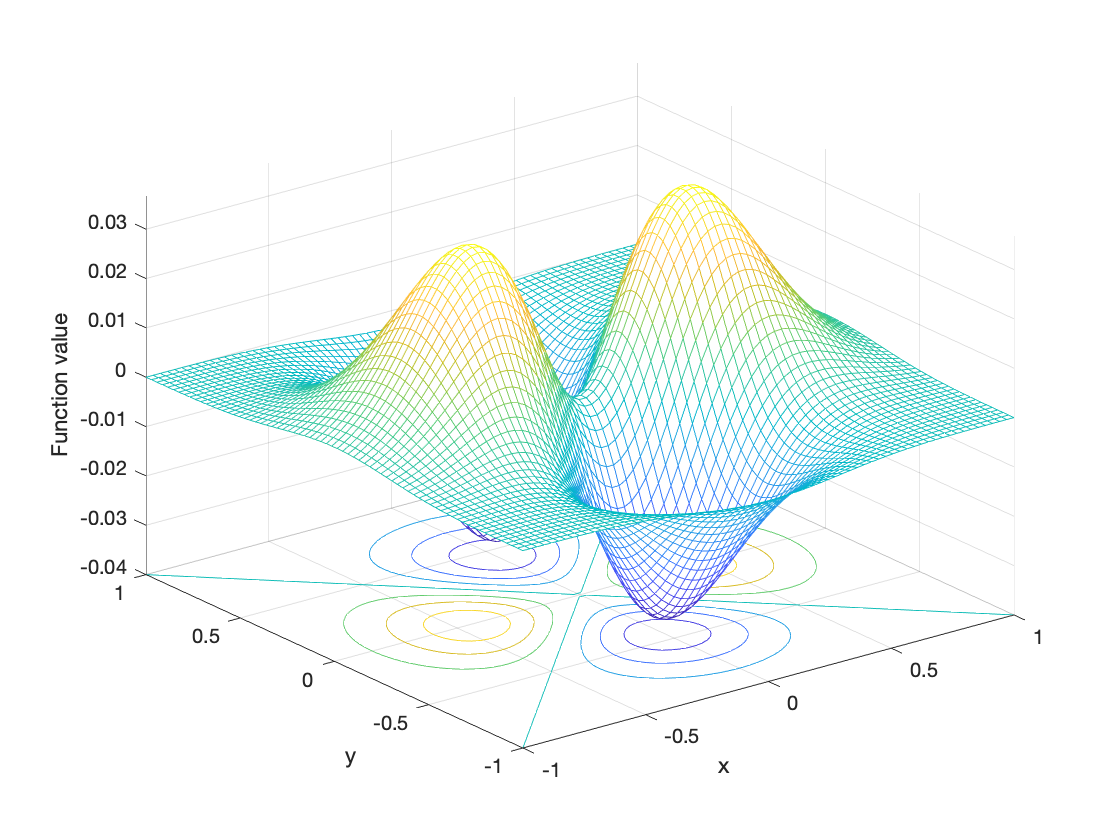

% A function "f" with a saddle point
f  = @(X,Y) 1/2*(X.^2 - Y.^2);

% make this only a local function: multiply by Gaussian "g"
% (otherwise, it has no minimizers)
sigma2  = .2;
g       = @(X,Y) exp( -(X.^2+Y.^2)/sigma2 );

% The function we are interested in is h=f*g
h       = @(X,Y) f(X,Y).*g(X,Y);

% Find partial derivatives (w.r.t. x and then y)
h_x  = @(X,Y) X.*g(X,Y) - 1/sigma2*(X.^2-Y.^2).*X.*g(X,Y);
h_y  = @(X,Y) -Y.*g(X,Y) - 1/sigma2*(X.^2-Y.^2).*Y.*g(X,Y);

% Make Hessian
h_xx = @(X,Y) 2*X.^4 + sigma2*(Y.^2+sigma2)-X.^2*(2*Y.^2+5*sigma2);
h_xy = @(X,Y) 2*X.*Y.*(X.^2-Y.^2);
h_yx = @(X,Y) h_xy(X,Y);
h_yy = @(X,Y) -2*Y.^4+5*Y.^2*sigma2-sigma2^2+X.^2.*( 2*Y.^2-sigma2);
hess = @(X,Y) g(X,Y)/(sigma2^2).*[ h_xx(X,Y), h_xy(X,Y); h_yx(X,Y), h_yy(X,Y) ];

% Make versions of the functions that take in xvec=[x;y]
F       = @(xvec) h(xvec(1),xvec(2));
Grad    = @(xvec) [h_x( xvec(1), xvec(2) ); h_y( xvec(1), xvec(2) ) ];
Hess    = @(xvec) hess( xvec(1), xvec(2) );

% Plot
figure(1); clf;
[X,Y]   = meshgrid( linspace( -1,1,70) );
Z       = h( X, Y);
meshc( X, Y, Z ); 
xlabel('x'); ylabel('y'); zlabel('Function value');

## Run both methods, for two different starting points

Newton's method:
Iter 0, distance(x,stationary point) is 3.00e-01


Iter 1, distance(x,stationary point) is 4.81e-02


Iter 2, distance(x,stationary point) is 4.78e-03


Iter 3, distance(x,stationary point) is 2.38e-05


Iter 4, distance(x,stationary point) is 6.49e-10


Iter 5, distance(x,stationary point) is 5.55e-17


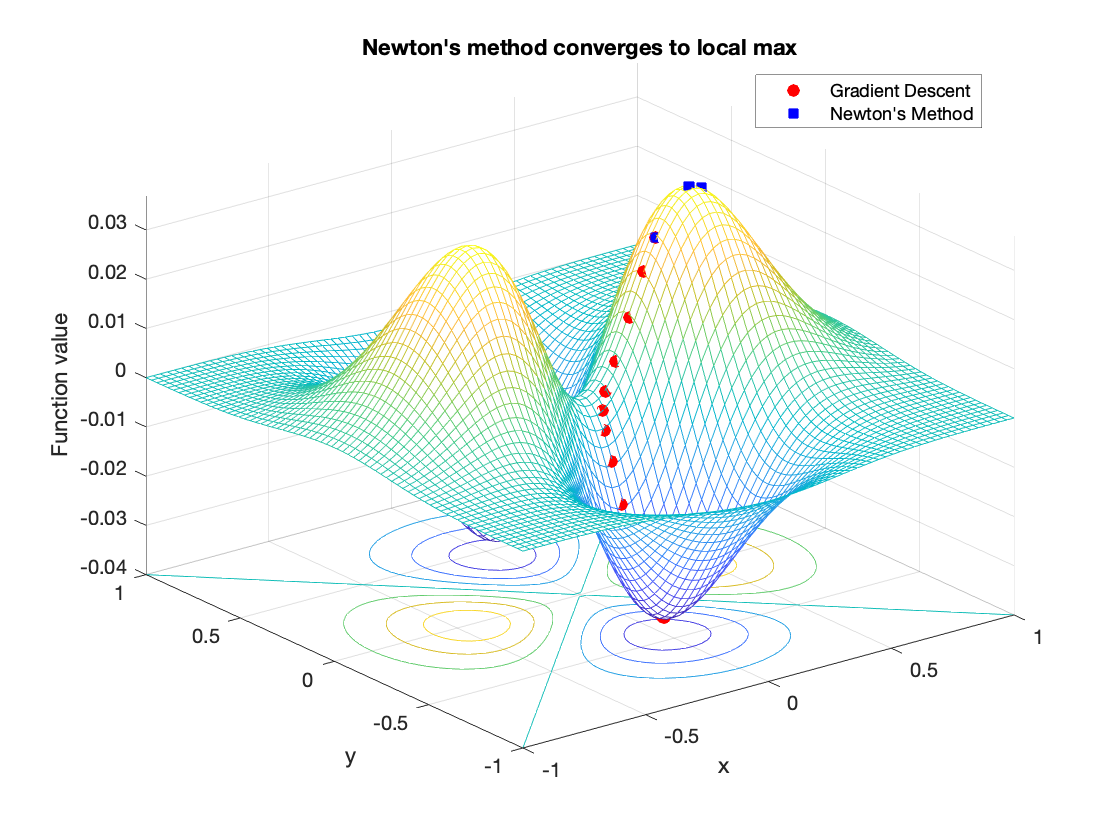

Newton's method:
Iter 0, distance(x,stationary point) is 1.00e-01


Iter 1, distance(x,stationary point) is 2.58e-02


Iter 2, distance(x,stationary point) is 3.49e-04


Iter 3, distance(x,stationary point) is 8.52e-10


Iter 4, distance(x,stationary point) is 0.00e+00


Iter 5, distance(x,stationary point) is 0.00e+00


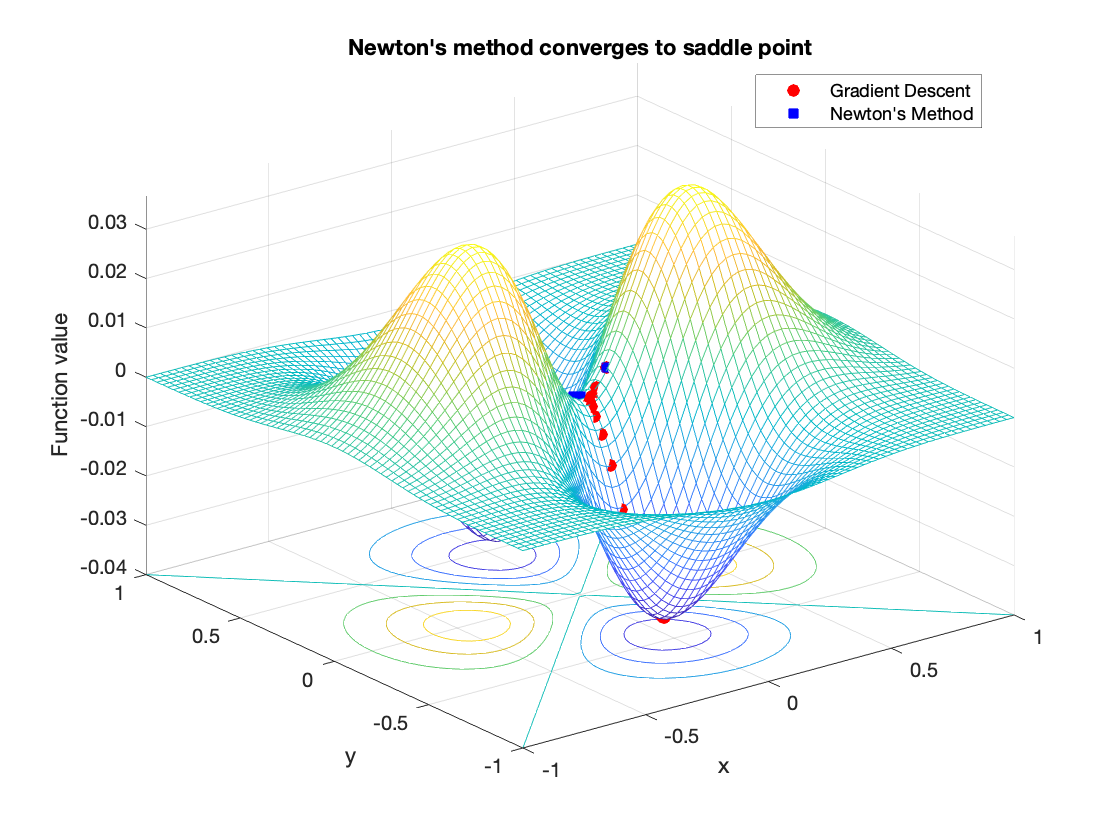

for trial = 1:2
    switch trial
        case 1
            x0      = [.3; -0.01 ]; xRef=[.447213595499958;0]; % Newton goes to local max!
        case 2
            x0      = [.1; -0.01 ]; xRef = [0;0];
    end
    
    figure(trial); clf;
    meshc( X, Y, Z );
    xlabel('x'); ylabel('y'); zlabel('Function value');
    hold all
    
    % Gradient Descent
    x       = x0;
    maxIter = 100;
    t       = 1/2; % stepsize
    for k = 1:maxIter
        handles=plot3( x(1), x(2), F(x)+.0001, 'ro','markersize',6 );
        handles.MarkerFaceColor=handles.Color;
        
        x   = x - t*Grad(x);
    end
    
    % Newton's method
    x       = x0;
    fprintf('Newton''s method:\nIter %d, distance(x,stationary point) is %.2e\n', 0, norm(x) );
    for k = 1:5
        handlesN=plot3( x(1), x(2), F(x)+.0001, 'bs','markersize',6 );
        handlesN.MarkerFaceColor=handlesN.Color;
        
        H   = Hess(x);
        x   = x - (H\Grad(x));
        fprintf('Iter %d, distance(x,stationary point) is %.2e\n', k, norm(x-xRef) );
    end
    
    switch trial
        case 1
            title('Newton''s method converges to local max');
        case 2
            title('Newton''s method converges to saddle point');
    end
    legend([handles,handlesN],'Gradient Descent','Newton''s Method','location','best');
end

disp('done')

done
